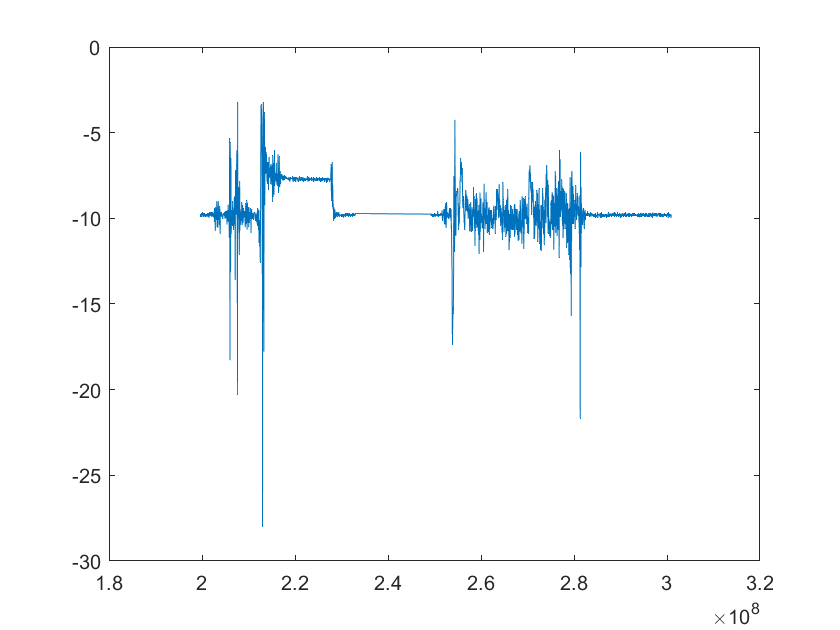

clear
close
clf
% load('R-Autotune Field Test 2.BIN-289401.mat')
%load('FPV Flight (12-9).BIN-120713.mat')
load('Maiden Voyage.BIN-29424.mat')

accx = IMU(:,6);
accy = IMU(:,7);
accz = IMU(:,8);
imuTime = IMU(:,2);

plot(IMU2(:,2),IMU2(:,8))

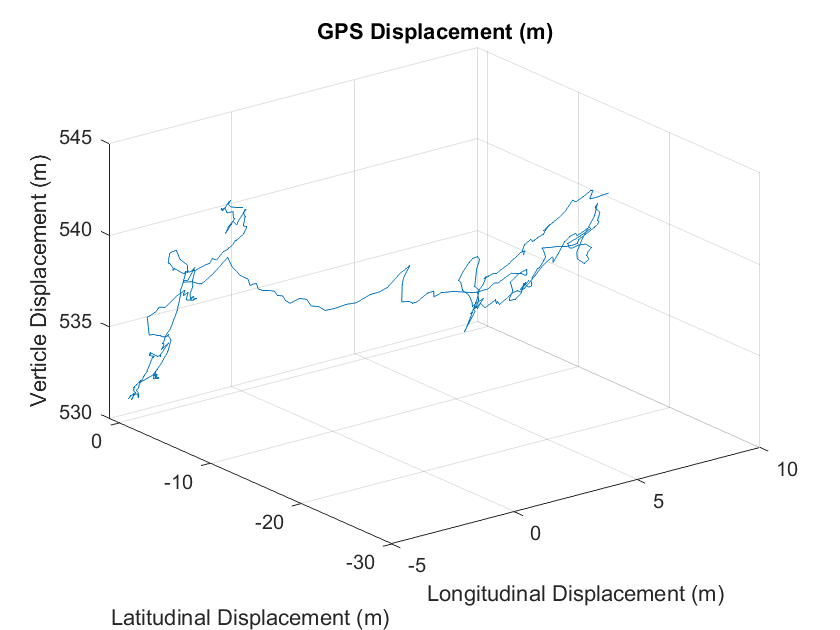


%the good stuff
%%% att roll roll desired
%atun: these are the auto tune parameters note rp rd and sp 
%see the mission planer review a log feature for what each variable is
%GPA for GPS error



llh = [GPS(:,8),GPS(:,9),GPS(:,10)]; % get llh for all times from gps

gpsTime = GPS(:,2);

latLongInitial = [GPS(1,8),GPS(1,9)]; % use the inital value for initial position
%may need to change this method as it may be inacurate (maybe average first few)

path = lla2flat(llh,latLongInitial,0,GPS(1,10));% use initial gps hieght as refrence
%maybe change because it is a const? or take an average?

pathTimed = [path,gpsTime/(10^6)]; %generate a path with time and scale gps time 
% measured in microseconds to seconds

%plot GPS displacement in 3d
%path z is negative so altitudes look positive (which is intuitivly expected)
plot3(path(:,2),path(:,1),-path(:,3))
grid on
title 'GPS Displacement (m)'
xlabel 'Longitudinal Displacement (m)', ylabel 'Latitudinal Displacement (m)', zlabel 'Verticle Displacement (m)';

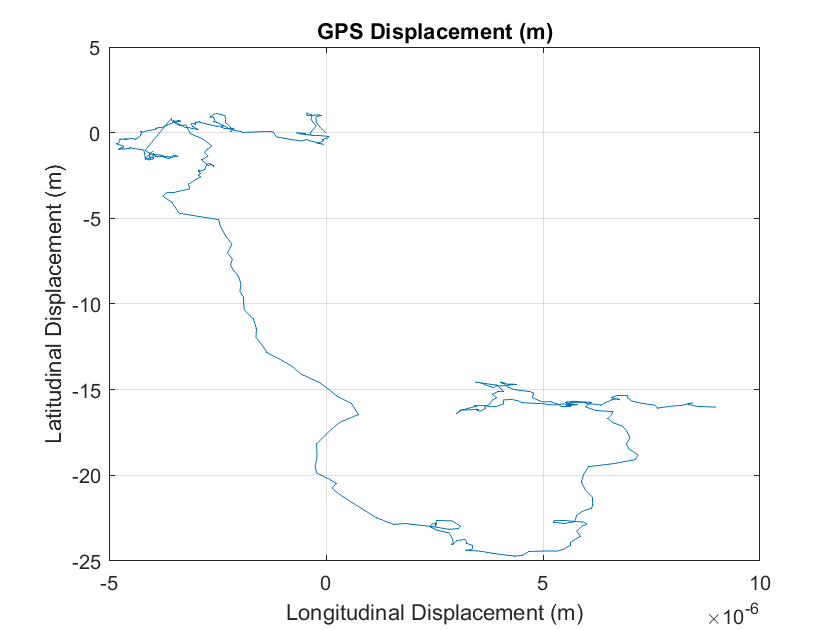


%plot GPS displacement top down
plot(path(:,2)/10^6,path(:,1))
grid on
title 'GPS Displacement (m)'
xlabel 'Longitudinal Displacement (m)', ylabel 'Latitudinal Displacement (m)';

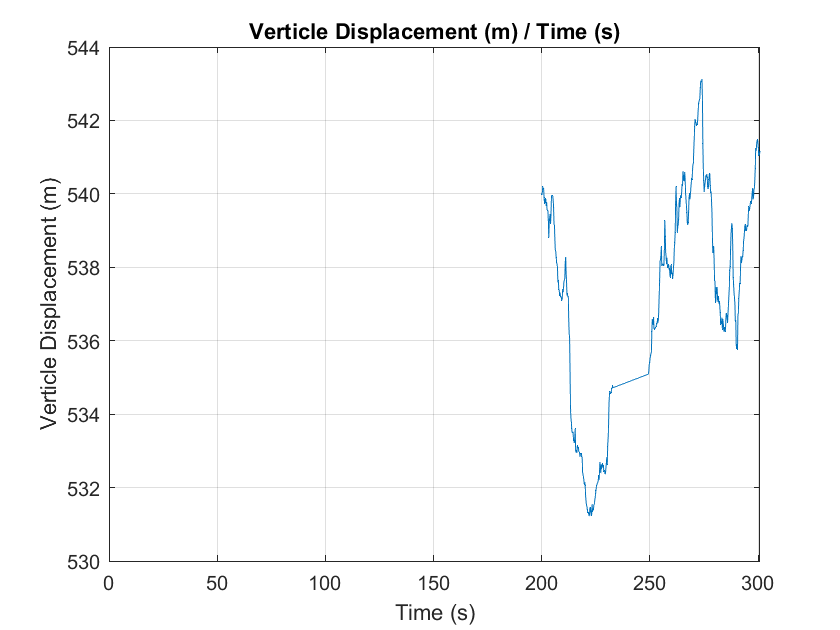


figure

limit = [0,gpsTime(length(gpsTime),1)/10^6]; % consider chashing GPSTime lenght (for clarity, not optimization)
plot(gpsTime/10^6,-path(:,3))
xlim(limit)
grid on
title 'Verticle Displacement (m) / Time (s)'
ylabel 'Verticle Displacement (m)', xlabel 'Time (s)'